## **Regression using gassuain processes:**

x = [-1.2 -1. -0.8 -0.6 -.4 -0.2 0 0.2 0.4 0.6];
y = [-2 -1 -0.5 -0.25 0.5 0.4 0. 1.2 1.7 1.4];

we have noisy sensor readings (indicated by errorbars) :

sigman = 0.1; % noise of the reading
sigmaf=1.1; % parameters of the GP - next to be computed by optimization
l=0.2; % lenght-scale of our GP with squared exponential kernel

first we will do a point prediction:

x_predict = 0.8;

We compute the kernel firts

K = get_kernel(x, x, sigmaf, l, sigman);
K_s = get_kernel(x_predict, x, sigmaf, l, 0);
K_ss = get_kernel(x_predict, x_predict, sigmaf, l, sigman);

so the best prediction for y will be the mean:

y_predict_mean = K_s*(K\y');
y_predict_var = diag(K_ss - K_s*(K\K_s'));

ploting the results for a point prediction:

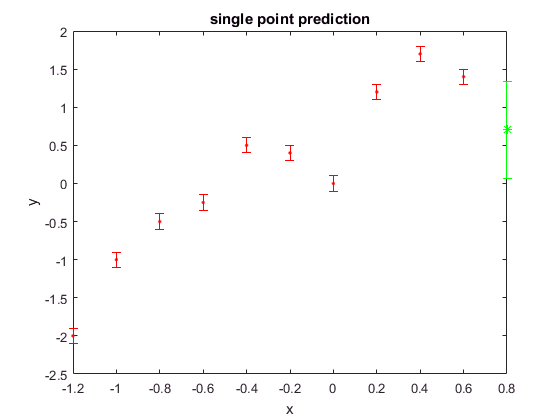

errorbar(x, y, sigman*ones(size(x)),'r.');
hold on;
errorbar(x_predict, y_predict_mean, y_predict_var,'g*');
xlabel('x');ylabel('y');title('single point prediction')
hold off

 Next we will predict 100 points:

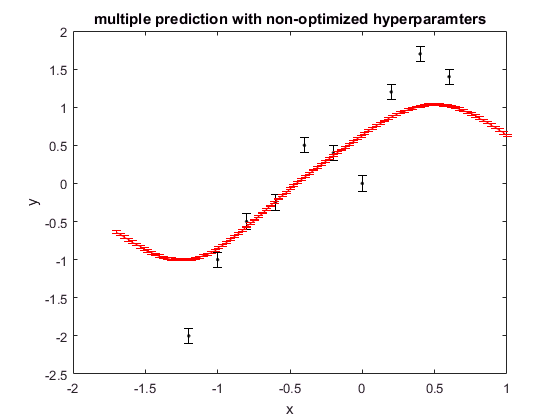

x_predict = linspace(-1.7,1,100);

sigmaf=0.1; l=0.5;

K = get_kernel(x, x, sigmaf, l, sigman);
K_s = get_kernel(x_predict, x, sigmaf, l, 0);
K_ss = get_kernel(x_predict, x_predict, sigmaf, l, sigman);

y_predict_mean = K_s*(K\y');
y_predict_var = diag(K_ss - K_s*(K\K_s'));

errorbar(x, y, sigman*ones(size(x)),'k.');
hold on;
%errorbar(x_predict, y_predict_mean, y_predict_var,'b-');
errorbar(x_predict, y_predict_mean, y_predict_var,'-r'); 
xlabel('x');ylabel('y');title('multiple prediction with non-optimized hyperparamters');
hold off;

Now we want to determine the best hyperparameters of our model. We will use MAP estimate of the hyperparameters:

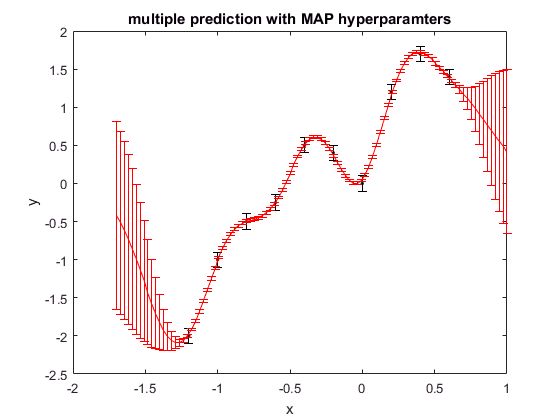

p = [1, 0.1];

fun = @(p) 0.5*(y*(get_kernel(x,x,p(1),p(2),sigman)\y') + log(det(get_kernel(x,x,p(1),p(2),sigman))) + numel(x)*log(2*pi));
p = fminsearch(fun,p);

sigmaf=p(1); l=p(2);

K = get_kernel(x, x, sigmaf, l, sigman);
K_s = get_kernel(x_predict, x, sigmaf, l, 0);
K_ss = get_kernel(x_predict, x_predict, sigmaf, l, sigman);

y_predict_mean = K_s*(K\y');
y_predict_var = diag(K_ss - K_s*(K\K_s'));

errorbar(x, y, sigman*ones(size(x)),'k.');
hold on;
%errorbar(x_predict, y_predict_mean, y_predict_var,'b-');
errorbar(x_predict, y_predict_mean, y_predict_var,'-r'); 
xlabel('x');ylabel('y');title('multiple prediction with MAP hyperparamters')
hold off;

In our GP we define squared exponential so the covariance will decrease as the points get far from each other. the lenght scale defines how rapid these changes will be and it is a hyperprameter of our model:

function K = get_kernel(x1,x2,sigmaf,l,sigman)
    k = @(x1,x2,sigmaf,l,sigman) (sigmaf^2)*exp(-(1/(2*l^2))*(x1-x2)^2) + (sigman^2);
    K = zeros(numel(x1),numel(x2));
    for i = 1:numel(x1)
        for j = 1:numel(x2)
            if i==j;K(i,j) = k(x1(i),x2(j),sigmaf,l,sigman);
            else;K(i,j) = k(x1(i),x2(j),sigmaf,l,0);end
        end
    end
end